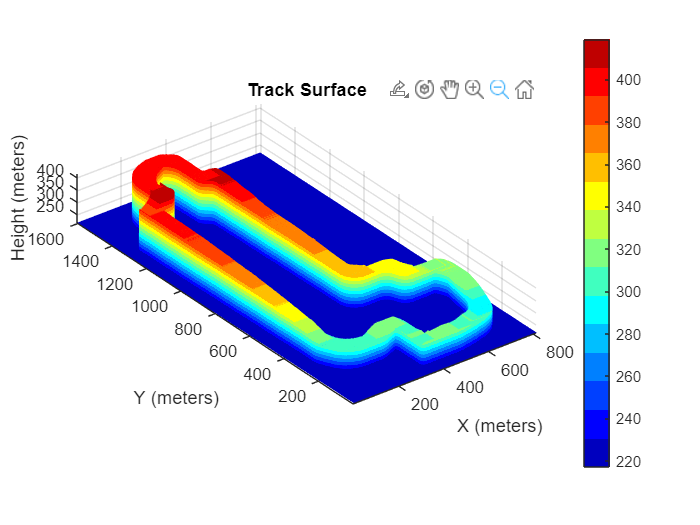

% Load the data from the CSV file
data = readmatrix('TrackSurface_Wider.csv');

% Normalize the data to the range [0, 1]
minHeight = min(data(:));
maxHeight = max(data(:));
normalizedData = (data - minHeight) / (maxHeight - minHeight);

% Apply a colormap to the normalized data
% For example, using the 'jet' colormap
colorData = jet;  % Get the RGB values for the 'jet' colormap
numColors = size(colorData, 1);  % Number of colors in the colormap

% Convert normalized data to indices of the colormap
colorIndices = round(normalizedData * (numColors - 1)) + 1;

% Create a color matrix (RGB) of the same size as the data matrix
colorMatrix = zeros(size(data, 1), size(data, 2), 3);  % Initialize with zeros
for i = 1:size(data, 1)
    for j = 1:size(data, 2)
        colorMatrix(i, j, :) = colorData(colorIndices(i, j), :);
    end
end

% Now you can use 'colorMatrix' with the 'surf' function
[X, Y] = meshgrid(1:size(data, 2), 1:size(data, 1));
surf(X, Y, data, data);

% Add labels, title, and color bar
xlabel('X (meters)');
ylabel('Y (meters)');
zlabel('Height (meters)');
title('Track Surface');

shading interp; % Interpolates colors across surfaces and lines
colormap jet(15);   % Set color map
colorbar;       % Show color scale

% Set equal scaling for the X and Y axes
axis equal;